Problem 2a

af=[-1, -0.5, -0.5, -0.5, -0.5;
-0.5, -1, -0.5, -0.5, -0.5;
-0.5, -0.5, -1, -0.5, -0.5;
-0.5, -0.5, -0.5, -1, -0.5;
-0.5, -0.5, -0.5, -0.5, -1];

v=[1;2;0;3;1];
eigenvals = eigeniter(af, v, 6);
answer = double(eigenvals'*af*eigenvals);
disp(answer);

   -3.0000



Problem 2b

disp(eig(af));

   -3.0000
   -0.5000
   -0.5000
   -0.5000
   -0.5000



The two are exactly the same.

Problem 3

mat = randi(10, 5);
disp(mat);

     6     4     5     8     8
     6    10     3     7     1
     1     4     2     1     4
     8     9     4     9     8
    10     5     8    10     8



vec1 = randi(5,[5,1]);
disp(vec1);

     2
     2
     4
     3
     4



vec2 = rand([5,1]);
disp(vec2);

    0.2364
    0.1771
    0.8296
    0.7669
    0.9345



vals1 = eigeniter(mat, vec1, 150);
vals2 = eigeniter(mat, vec2, 150);
disp(double(vals1'*mat*vals1));

   30.9761



disp(double(vals2'*mat*vals2));

   30.9761



disp(eig(mat));

   30.9761
   -3.6689
   -1.1809
    2.2857
    6.5880



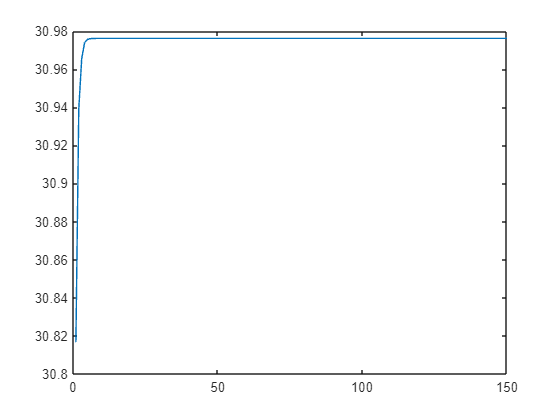

vecc1 = plotter(mat, vec1, 150);
vecc2 = plotter(mat, vec2, 150);
plot(vecc1);

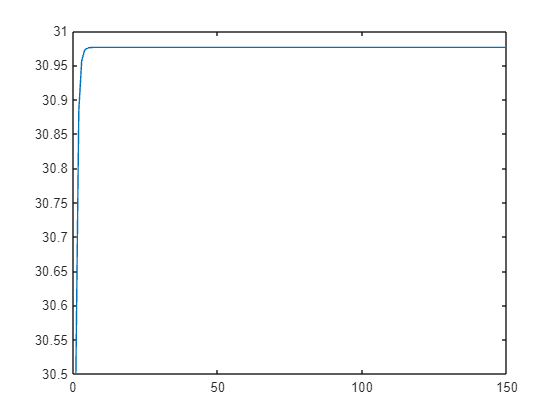

plot(vecc2);

The answers are all the exact same for the largest eigenvalue. It does not matter what the initial vector is; the rate of convergence is roughly the same for both vectors in this case, as they both converge to the largest eigenvalue around the same time.

function eigval = eigeniter(m, v, iters)
for a = 1:iters
    u = m*v/norm(m*v);
    v = u;
end
eigval = v;
end

function vecplot = plotter(m,v,iters)
for a = 1:iters
    u = m*v/norm(m*v);
    vec(a) = double(u'*m*u);
    v = u; 
end
vecplot = vec;
end